## Polar Overturning Conceptual Model

#### Live script to run experiments in paper and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20

Housekeeping:

clear
close all
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84) 
    
    parpool('local',16) 
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


Define universal parameters:

[geophysical_parameters, static_parameters] = define_POC_static_parameters ;
plot_options = define_POC_plot_options ;

Exp 1: Northern hemisphere Fram Strait/Barents Sea Opening.

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_can',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;

Elapsed time is 16.883040 seconds.


theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
model1 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(model1)

 Solutions for experiment: [Exp.~1 Fram Strait+BSO] with file suffices: [NH_FSBSO_can]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500,
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.2697   0.2697   0.2697,
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -1.0838  -1.0838  -1.0838,
 Overflow Water:             1.4288   1.4288   1.4288 |  34.9552  34.9552  34.9552 |  -3.6723  -3.6723  -3.6723,
 Shelf    Water:            -2.0610  -2.0610  -2.0610 |  37.6287  37.6287  37.6287 |  -0.2297  -0.2297  -0.2297,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.1889  -0.1889  -0.1889,
 Sea ice to shelf:    

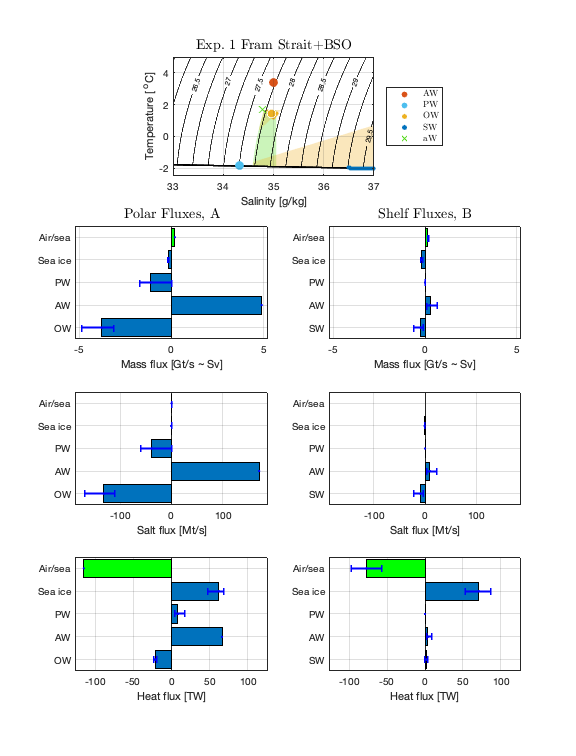

plot_POC_solution(model1)

Exp 2: Modified Northern hemisphere Fram Strait/Barents Sea Opening (higher Q).

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_mod',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;

Elapsed time is 14.042216 seconds.


theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
model2 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(model2)

 Solutions for experiment: [Exp.~2 Fram Strait+BSO high ${\cal Q}$] with file suffices: [NH_FSBSO_mod]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500,
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   3.3072   3.3072   3.3072,
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -0.9941  -0.9941  -0.9941,
 Overflow Water:            -1.4517  -1.4517  -1.4517 |  34.8222  34.8222  34.8222 |  -3.7762  -3.7762  -3.7762,
 Shelf    Water:            -1.8969  -1.8969  -1.8969 |  34.8287  34.8287  34.8287 |  -3.3037  -3.3037  -3.3037,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.1728  -0.1728  -0.1728,
 Sea i

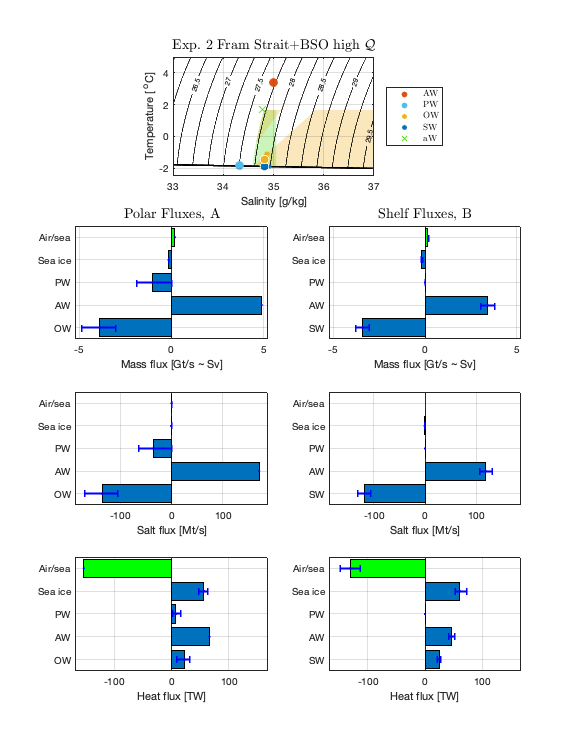

plot_POC_solution(model2)

Exp X: Modified Northern hemisphere Fram Strait/Barents Sea Opening (intermediate Q).

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_int',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;

Elapsed time is 16.496013 seconds.


theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
modelX = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(modelX)

 Solutions for experiment: [Exp.~X Fram Strait+BSO intermediate ${\cal Q}$] with file suffices: [NH_FSBSO_int]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500,
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0471   0.0471   0.0471,
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -4.4061  -4.4061  -4.4061,
 Overflow Water:             1.4085   1.4085   1.4085 |  34.8277  34.8277  34.8277 |  -0.4207  -0.4207  -0.4207,
 Shelf    Water:            -1.9361  -1.9361  -1.9361 |  35.5010  35.5010  35.5010 |  -0.0296  -0.0296  -0.0296,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.1111  -0.1111  -0.1111

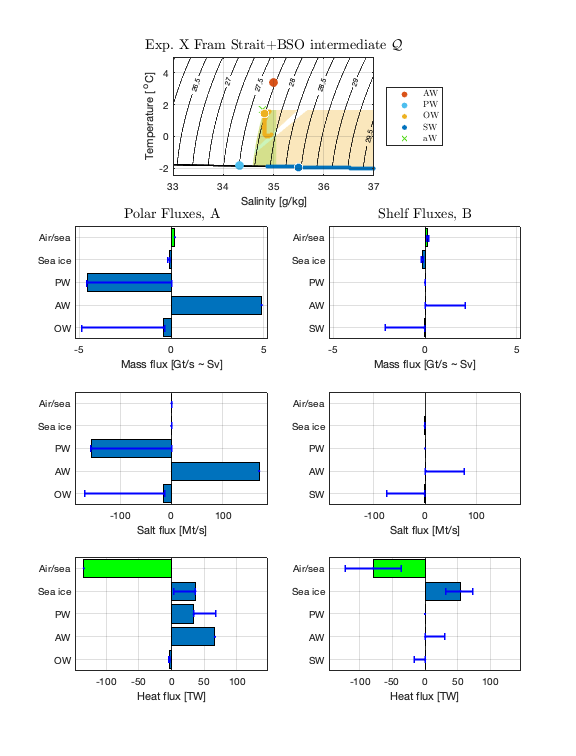

plot_POC_solution(modelX)

Make figure showing entrainment/shelf circulation tradeoff

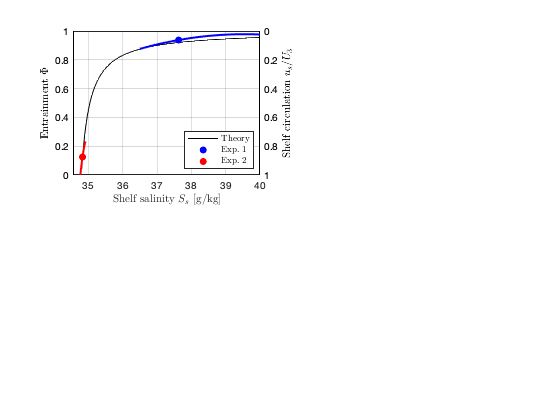

plot_POC_tradeoff(model1,model2)

Exp 3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_range',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model3 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model3)

 Solutions for experiment: [Exp.~3 Fram Strait+BSO various ${\cal Q}$] with file suffices: [NH_FSBSO_range]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500,
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0166   1.5568   4.7388,
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -4.8296  -1.8764  -0.0068,
 Overflow Water:            -1.8931   0.0502   1.6148 |  34.6813  34.8606  34.9598 |  -4.7469  -2.9042  -0.0042,
 Shelf    Water:            -2.1990  -1.9597  -1.8865 |  34.6488  35.8998  39.9577 |  -4.7423  -1.5391  -0.0001,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.2128  -0.1618  -0.1034,
 

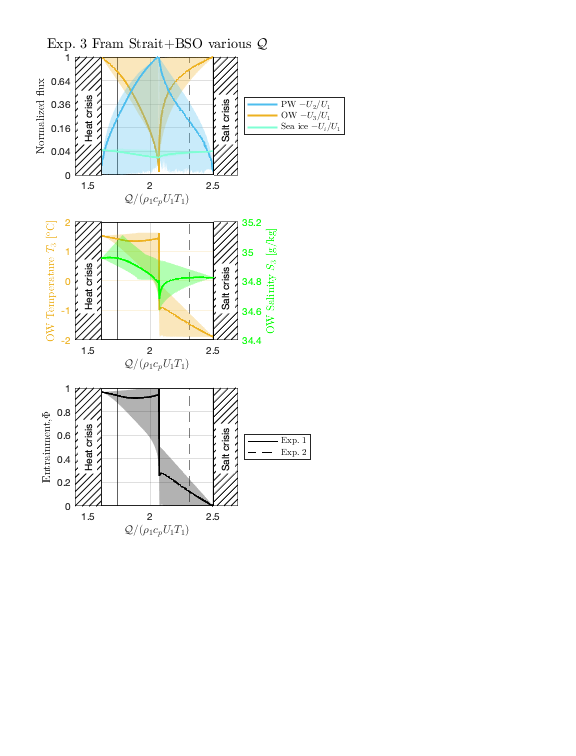

plot_POC_solutions1(model3,model1,model2)

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_sens',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model4 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model4)

 Solutions for experiment: [Exp.~4 Fram Strait+BSO sensitivity] with file suffices: [NH_FSBSO_sens]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   3.1667   5.1458   7.1250,
 Atlantic Water to shelf:    2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   0.0052   1.9014   7.1246,
 Polar    Water:            -1.9174  -1.8654  -1.8129 |  33.3813  34.2866  35.1791 |  -7.3080  -2.0430  -0.0000,
 Overflow Water:            -1.9483   0.0488   2.4027 |  33.8611  34.8469  35.7778 |  -7.1583  -3.4186  -0.0000,
 Shelf    Water:            -2.1964  -1.9576  -1.8415 |  33.7979  35.8370  39.9999 |  -7.1559  -1.8838  -0.0000,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.3816  -0.1606  -0.0000,
 Sea ice 

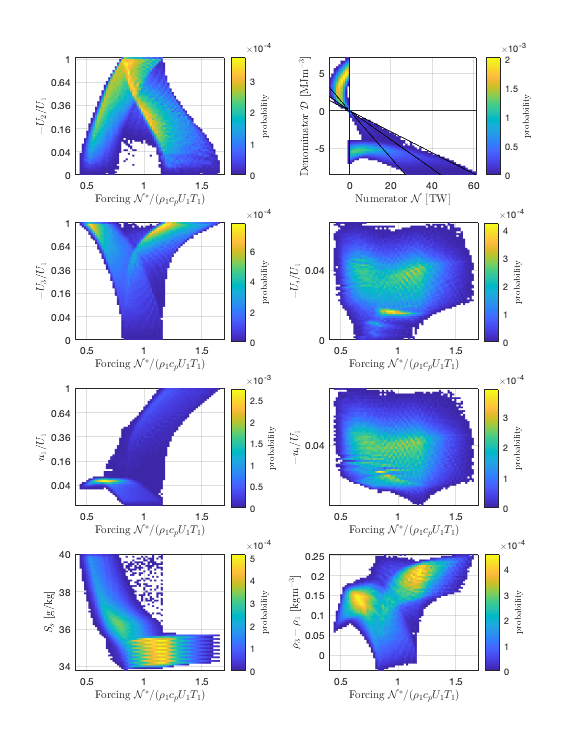

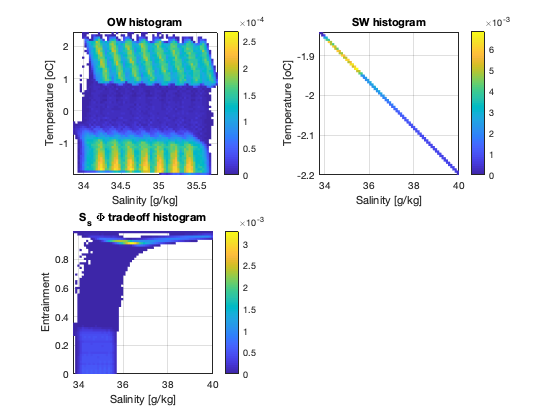

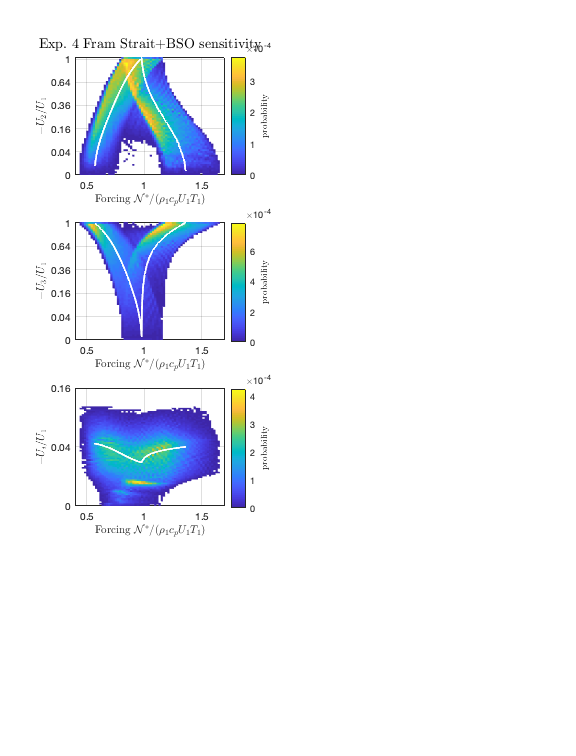

plot_POC_solutions2(model4,model3)

Exp 5: Northern hemisphere Fram Strait/Barents Sea Opening with various S_2 values.

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_S2_range',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model5 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model5)

 Solutions for experiment: [Exp.~5 Fram Strait+BSO various $S_2$] with file suffices: [NH_FSBSO_S2_range]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500,
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.1212   0.9230   1.7879,
 Polar    Water:            -1.8675  -1.8096  -1.7518 |  30.3235  32.3235  34.3235 |  -4.0020  -1.6248  -0.0164,
 Overflow Water:             0.2296   0.7595   1.4291 |  34.6983  34.7868  34.9552 |  -4.7575  -3.1785  -0.8635,
 Shelf    Water:            -2.0610  -1.9461  -1.9035 |  34.9410  35.6696  37.6287 |  -1.7686  -0.9007  -0.1038,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.2046  -0.1371  -0.0683,
 Se

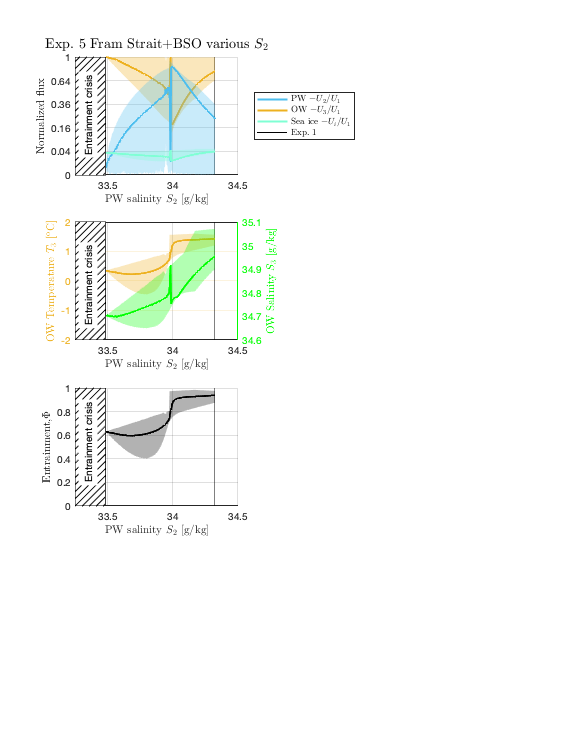

plot_POC_solution3(model5,model1)

DEBUG! Exp Y: Modified Northern hemisphere Fram Strait/Barents Sea Opening (small S2).

[this_case,dynamic_parameters] = define_POC_base_case('NH_FSBSO_small_S2',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;

Elapsed time is 14.480738 seconds.


theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
modelY = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(modelY)

 Solutions for experiment: [Exp.~Y Fram Strait+BSO small $S_2$] with file suffices: [NH_FSBSO_small_S2]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500,
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   1.7813   1.7813   1.7813,
 Polar    Water:            -1.8189  -1.8189  -1.8189 |  32.6475  32.6475  32.6475 |  -0.0155  -0.0155  -0.0155,
 Overflow Water:             0.3522   0.3522   0.3522 |  34.7023  34.7023  34.7023 |  -4.7584  -4.7584  -4.7584,
 Shelf    Water:            -1.9097  -1.9097  -1.9097 |  35.0472  35.0472  35.0472 |  -1.7582  -1.7582  -1.7582,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.1694  -0.1694  -0.1694,
 Sea 

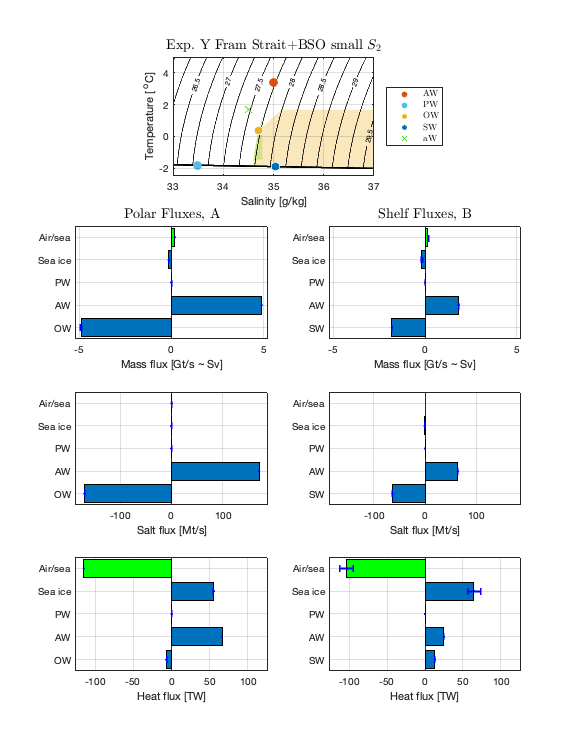

plot_POC_solution(modelY)

Compare numerical results to theory

 Exp.~4 has [525199] solutions, found: [215] salt crises, [101] heat crises, [646] OW emergencies.


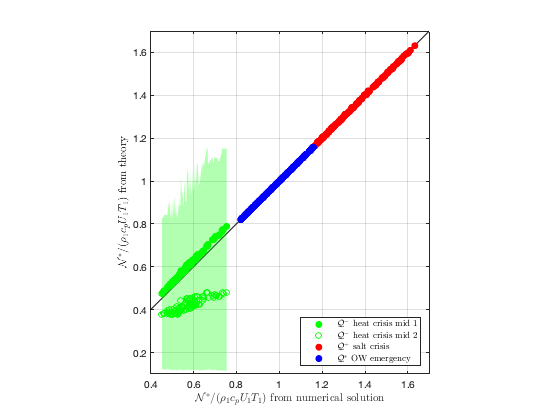

plot_POC_solutions_and_theory(model4)

Exp 6: Southern hemisphere.

[this_case,dynamic_parameters] = define_POC_base_case('SH_can',static_parameters,geophysical_parameters) ;
[sens,vals] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;

Elapsed time is 13.686511 seconds.


theory = compute_POC_theory(dynamic_parameters,static_parameters,geophysical_parameters) ;
model6 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens,'vals',vals,'theory',theory) ;
report_POC_results(model6)

 Solutions for experiment: [Exp.~6 Antarctic] with file suffices: [SH_can]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |  26.0000  26.0000  26.0000,
 Atlantic Water to shelf:    0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |   2.3170   2.3170   2.3170,
 Polar    Water:            -1.8868  -1.8868  -1.8868 |  34.6548  34.6548  34.6548 | -17.4900 -17.4900 -17.4900,
 Overflow Water:            -0.7231  -0.7231  -0.7231 |  35.1098  35.1098  35.1098 |  -8.5076  -8.5076  -8.5076,
 Shelf    Water:            -1.9688  -1.9688  -1.9688 |  36.0589  36.0589  36.0589 |  -2.2038  -2.2038  -2.2038,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.2624  -0.2624  -0.2624,
 Sea ice to shelf:         -10.000

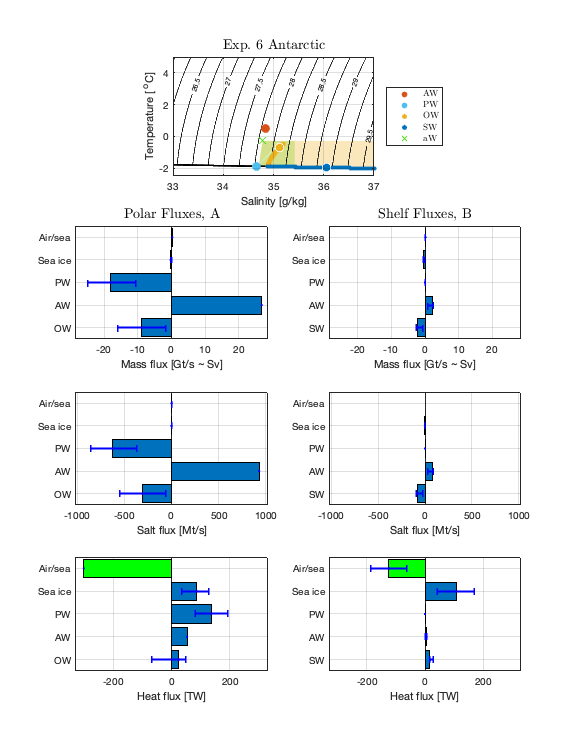

plot_POC_solution(model6)

Exp 7: Southern hemisphere with many Q values

[this_case,dynamic_parameters] = define_POC_base_case('SH_range',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model7 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model7)

 Solutions for experiment: [Exp.~7 Antarctic various ${\cal Q}$] with file suffices: [SH_range]:

                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |  26.0000  26.0000  26.0000,
 Atlantic Water to shelf:    0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |   0.0237  11.8304  25.9629,
 Polar    Water:            -1.8868  -1.8868  -1.8868 |  34.6548  34.6548  34.6548 | -26.0733  -5.7933  -0.0101,
 Overflow Water:            -1.9172  -1.1314  -0.3496 |  34.6277  35.1019  35.1771 | -25.5272 -19.9004  -0.0517,
 Shelf    Water:            -2.1774  -1.9577  -1.9098 |  35.0491  35.8698  39.5945 | -25.4979 -11.4759  -0.0021,
 Sea ice:                  -10.0000 -10.0000 -10.0000 |   4.0000   4.0000   4.0000 |  -0.7674  -0.5946  -0.1228,
 Sea ice to s

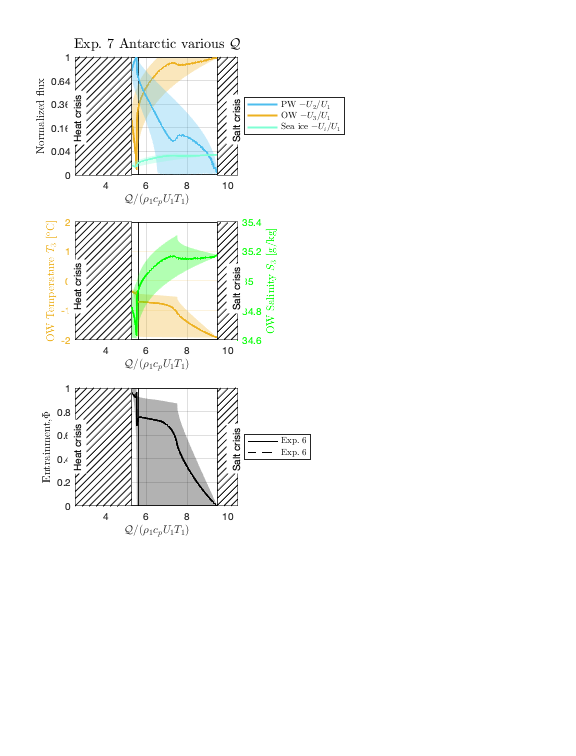

plot_POC_solutions1(model7,model6,model6)

 Exp.~7 has [255] solutions, found: [4] salt crises, [3] heat crises, [4] OW emergencies.


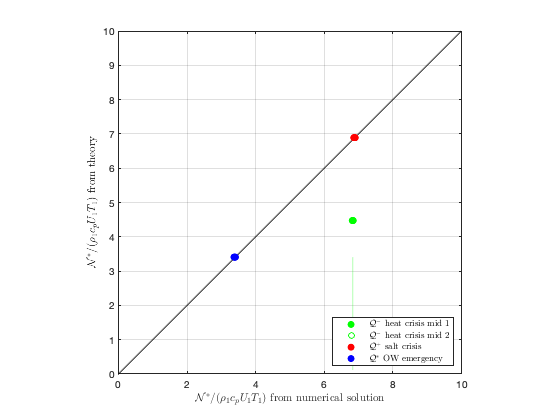

plot_POC_solutions_and_theory(model7)

Exp 8: Southern hemisphere Antarctic as a whole

return
%% Need to re-run this one from scratch!
[this_case,dynamic_parameters] = define_POC_base_case('SH_sens',static_parameters,geophysical_parameters) ;
[sens,~] = compute_POC_solutions(this_case,dynamic_parameters,static_parameters,geophysical_parameters) ;
model8 = struct('base_case',this_case,'static_parameters',static_parameters,'geophysical_parameters',geophysical_parameters,'plot_options',plot_options,'dynamic_parameters',dynamic_parameters,'sens',sens) ;
report_POC_results(model8)
plot_POC_solutions2(model8,model7)
plot_POC_solutions_and_theory(model8)